# The mextractor function

# in the astronomy & astrophysics toolbox for MATLAB

## Description:

The mextractor function is a method in the [SIM class](https://webhome.weizmann.ac.il/home/eofek/matlab/doc/SIM.html) that enable source finding and measurment in astronomical images. The function uses matched filter to locate sources and perform variery of measurments, including aperture and PSF photometry. The function can automaticaly find the image PSF for matched filter, and perform a careful background subtraction which is critical for many purposes.

This file is accessible through the `manual` package (i.e. `manual.mextractor`).

## Credit

If you are using this code or products in your scientific publication please give a reference to [Ofek (2014; ascl.soft 07005)](http://adsabs.harvard.edu/abs/2014ascl.soft07005O).

## License

Unless specified otherwise this code and products are released under the GNU general public license version 3.

## Installation

See[ http://weizmann.ac.il/home/eofek/matlab/doc/install.html ](http://webhome.weizmann.ac.il/home/eofek/matlab/doc/install.html)for installation instruction and additional documentation.

# Reduction steps

mextractor is a flexible code to find, extract and measure sources in astronomical images. mextractor can run on a single or multiple images, and can find sources and or measure user supplied list of sources. mextractor is part of the SIM class and uses the information available within the SIM object, and if some information does not exist, mextractor will generate this information and store it in the SIM object. For example, if the SIM object contains the background and PSF, this information will be used by mextractor, and if it does not exist, mextractor will generate this information.

The user can control the behavior of mextractor via a large number of keywords and full list of the keywords is available by typing:

help mextractor
% or

ans =   SIM with properties:

               Im: [4096×2048 single]
    ImageFileName: ''
           BackIm: []
            ErrIm: []
         WeightIm: []
              Cat: []
              Col: []
          ColCell: []
         ColUnits: []
         SortedBy: []
      SortedByCol: []
             Name: []
           Source: []
        Reference: []
          Version: []
           Header: {376×3 cell}
              WCS: [1×1 struct]
         UserData: []
             Mask: []
          MaskDic: []
              PSF: []
           ErrPSF: []
           ParPSF: {}
           CooPSF: []


doc mextractor

mextractor perform (optionally) the following steps:

gain correction - correct the images gain to 1. This is performed using the `gain_correct` method.

PSF extraction - In order to extract the PSF, `mextractor` call itself to find the brightest sources and use them to generate the PSF. By default, this is done using the `psf_cat_selector` and `psf_estimator` methods.

Mask generation - `mextractor` propogate and add bit masks to the `MASK` object associated with the `SIM` image.

Background and noise estimation - Estimate the background and noise images using the `background` method, and subtract the background from the image. The background estimation is a critical step for source detection. Any small bias in the background estimation may lead to the detection of false sources, or missing real sources. The default method for background and noise estimation (the 'mode_fit' option in the `background` function) is to fit a Gaussian to the histogram of counts.

Filter the image - The source detection is done via matched filter. However, `mextractor` can perform cross-correlation with several filters. For example, the stellar PSF as well as some exdended PSFs for galaxies identification. This allows the user to find both faint stars and galaxies in a single mextractor call.

Measurments - `mextractor` performs a wide range of measurments on the detected sources. This include, positional information, moments, flag propogation, aperture photometry, PSF photometry, contour photometry, S/N measurments, WCS information, neighbour searches, as well as time-position dependent parameters  like, airmass, and parallactic angle, azimuth and altitude. See help for complete list of parameters.

Source flagging - `mextractor` can remove and/or flag problematic sources. For example, it allows to locate sources on top of diffraction spikes, cosmic rays (via Hypothesis testing), sources in location of background with strong gradients, and more.

# Examples

## Simple use

`mextractor` is a method of the `SIM` class, and therefore it works on `SIM` objects. The first stage is to read an image(s) into a `SIM` container. This is done using functions in the `FITS` static class:

S=FITS.read2sim('test_PTF*100037_c02.fits');

  Set gain to 1
mextractor first pass - Constructing optimal PSF
  Set gain to 1
  No filter found - Use DefFilter
  Estimate images background and std
 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 212933.370859 



 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 922844.488936 



 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 144980.484556 



  Subtract background
  Filter image number 1 - use 1 filters
    Threshold image and locate local maxima
    Extracting 2599 sources
  Calculate 1st and 2nd moments


mextractor second pass - Source detection and measurments
  Subtract background


  Filter image number 1 - use 2 filters
    Threshold image and locate local maxima
    Extracting 5551 sources
  Calculate 1st and 2nd moments
    Calculate PSF photometry
    Calculate IL aperture photometry (using aper_phot)


S(1)   % display the content of the first element in the SIM object

ans =   SIM with properties:

               Im: [4096×2048 single]
    ImageFileName: ''
           BackIm: [4096×2048 double]
            ErrIm: [4096×2048 double]
         WeightIm: []
              Cat: [5551×37 double]
              Col: [1×1 struct]
          ColCell: {1×37 cell}
         ColUnits: []
         SortedBy: {'YWIN_IMAGE'}
      SortedByCol: 2
             Name: []
           Source: []
        Reference: []
          Version: []
           Header: {2×3 cell}
              WCS: []
         UserData: []
             Mask: [4096×2048 uint32]
          MaskDic: []
              PSF: [21×21 double]
           ErrPSF: []
           ParPSF: {}
           CooPSF: []


The variable S is a `SIM` array of one ore more images. In this example, only the `Im`, `Header` and `WCS` fields is populated.

Next, we can run mextractor, with the same output as input:

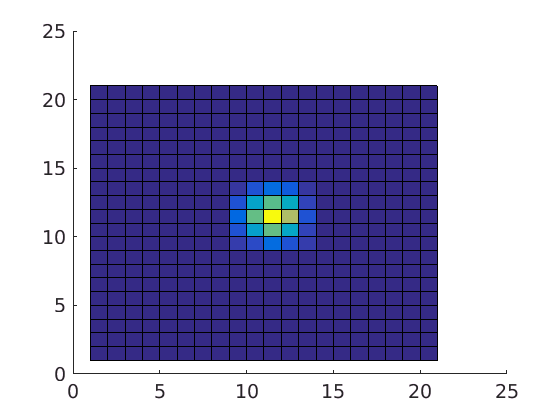

S=mextractor(S);

S(1)

After running mextractor, several other fields in S are populated. Specifically, the `BackIm` field contains the background image, the `ErrIm` field contains the background noise image, the `PSF` field contains the image point spread function, and `Cat` contains the catalog of sources detected and measured by mextractor.

For example, the PSF is stored in the PSF field and it can be displayed using:

surface(S(1).PSF)

ans =        867.32       2.6424          867            3       1.3096       2.2408     0.026954          NaN          NaN       140.61       1773.4        10.64        3.532       9.8244       14.678       447.02       301.41       15.374      0.73209       125.95       177.23       166.08         1114       2136.6       2223.4       2342.9       3359.8       150.76       265.15        476.1       681.57       885.87       1632.8        39.81       1662.6         45.5            0
       927.97       3.2365          928            3       1.3525       1.8169     0.042438          NaN          NaN       151.21       1778.7        6.744       3.8042       10.932       9.3389       473.35       224.77       15.312      0.51557       35.143       66.033       53.178       593.42       1421.5       2716.5       4906.3       7164.6        136.6       271.46       485.74       694.88       897.44       1627.5       39.748       1642.5       43.297            0
       830.38        3.724    

The following command will display the first 10 lines in the catalog:

S(1).Cat(1:10,:)

ans =     'XWIN_IMAGE'    'YWIN_IMAGE'    'XPEAK_IMAGE'    'YPEAK_IMAGE'    'X2WIN_IMAGE'    'Y2WIN_IMAGE'    'XYWIN_IMAGE'    'ALPHAWIN_J2000'    'DELTAWIN_J2000'    'PEAKF_VAL'    'PEAKF_VALTOT'    'SN'    'SN_UNF'    'SN_PSF'    'SN_ADD_1'    'FLUX_PSF'    'FLUXERR_PSF'    'MAG_PSF'    'MAGERR_PSF'    'PSF_CHI2'    'PSF_CHI2BACK'    'PSF_CHI2CR'    'FLUX_APER_1'    'FLUX_APER_2'    'FLUX_APER_3'    'FLUX_APER_4'    'FLUX_APER_5'    'FLUXERR_APER_1'    'FLUXERR_APER_2'    'FLUXERR_APER_3'    'FLUXERR_APER_4'    'FLUXERR_APER_5'    'BACK'    'BACK_STD'    'BACK_ANNULUS'    'STD_ANNULUS'    'FLAGS'


The catalog column names are stored as a cell array in:

S(1).ColCell

ans =         XWIN_IMAGE: 1
        YWIN_IMAGE: 2
       XPEAK_IMAGE: 3
       YPEAK_IMAGE: 4
       X2WIN_IMAGE: 5
       Y2WIN_IMAGE: 6
       XYWIN_IMAGE: 7
    ALPHAWIN_J2000: 8
    DELTAWIN_J2000: 9
         PEAKF_VAL: 10
      PEAKF_VALTOT: 11
                SN: 12
            SN_UNF: 13
            SN_PSF: 14
          SN_ADD_1: 15
          FLUX_PSF: 16
       FLUXERR_PSF: 17
           MAG_PSF: 18
        MAGERR_PSF: 19
          PSF_CHI2: 20
      PSF_CHI2BACK: 21
        PSF_CHI2CR: 22
       FLUX_APER_1: 23
       FLUX_APER_2: 24
       FLUX_APER_3: 25
       FLUX_APER_4: 26
       FLUX_APER_5: 27
    FLUXERR_APER_1: 28
    FLUXERR_APER_2: 29
    FLUXERR_APER_3: 30
    FLUXERR_APER_4: 31
    FLUXERR_APER_5: 32
              BACK: 33
          BACK_STD: 34
      BACK_ANNULUS: 35
       STD_ANNULUS: 36
             FLAGS: 37


or as a structure array in:

S(1).Col

eran     34278  2.9  0.0 180076 77568 pts/39   S    16:06   0:03 ds9
ds9 is already open


To display the image with the positions of the extracted sources.

ds9(S(1))
ds9.plot(S(1))

We can manipulate and plot columns of the catalog. For example, to display the detection S/N vs. PSF magnitude:

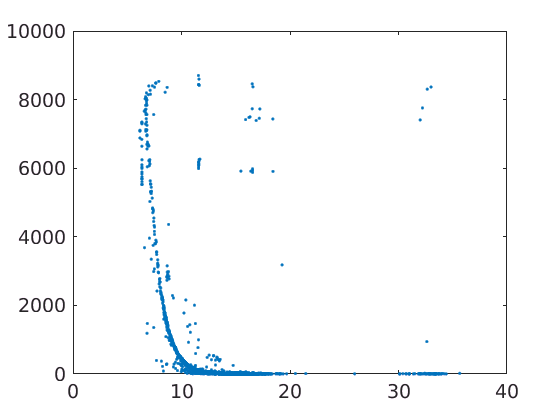

Col = S(1).Col;
plot(S(1).Cat(:,Col.MAG_PSF),S(1).Cat(:,Col.SN),'.')

As expected the S/N is larger for bright stars. However, at the top of the diagram, there are several outliers (with S/N>6000 and Mag>10). You can choose this sources and plot their position on the image:

Col = S(1).Col;
Flag = S(1).Cat(:,Col.MAG_PSF)>10 & S(1).Cat(:,Col.SN)>6000;
ds9(S(1))

eran     34278  3.5  0.0 180076 77568 pts/39   S    16:06   0:05 ds9
ds9 is already open


ds9.plot( S(1).Cat(Flag,[Col.XWIN_IMAGE, Col.YWIN_IMAGE]),'bs')

Now, the nature of these sources is clear - these are saturated objects.

## `Input parameters`

`You can change the settings/input parameters of mextractor either uby adding a pairs of keyword,value pairs:`

S=mextractor(S,'ZP',27,'MagInLuptitude',false,'Thresh',8);

[1M> 
[1A----- SExtractor 2.5.0 started on 2017-01-15 at 09:51:51 with 1 thread

[1M> Setting catalog parameters
[1A[1M> Reading detection filter
[1A[1M> Initializing catalog
[1A[1M> Looking for tp609482ef_26c6_4ccf_bb5f_4e9c0ea41c1d
[1AMeasuring from: "PTF_survey"  / 2048 x 4096 / 32 bits FLOATING POINT data
Detection+Measurement image: [1M> Setting up background maps
[1A[1M> Setting up background map at line:  128
[1A[1M> Setting up background map at line:  256
[1A[1M> Setting up background map at line:  384
[1A[1M> Setting up background map at line:  512
[1A[1M> Setting up background map at line:  640
[1A[1M> Setting up background map at line:  768
[1A[1M> Setting up background map at line:  896
[1A[1M> Setting up background map at line: 1024
[1A[1M> Setting up background map at line: 1152
[1A[1M> Setting up background map at line: 1280
[1A[1M> Setting up background map at line: 1408
[1A[1M> Setting up background map at line: 1536
[1A[1M> Setting up background map at line: 1664
[1A[

A complete list of keywords is available in the help of `mextractor`.

Alternatively you can use the `InArg.epar` command to edit the arguments and save them as your default parameters:

InArg.epar('mextractor')

eran     21137  0.7  0.0 217752 116412 pts/39  S    09:36   0:11 ds9
ds9 is already open


## Control the output catalog columns

The `ColCell` input argument controls the mextractor catalog output colums. For example, to produce a catalog with only two columns, the X and Y positions:

S=mextractor(S,'ColCell',{'XWIN_IMAGE','YWIN_IMAGE'});

## List of catalog output columns (source attributes)

A list of all possible output columns (source attributes) are listed below. Some attributes may have indexed multiple entries (marked by [_#]). Examples, are aperture photometry in multiple apertures.

- NUMBER - Source index. Note that if the output is sorted (i.e., 'SortOut' input argument) then this number does not corresponds to the entry number.

- ISFORCE - A logical flag (0 | 1) indicating if the source was found by filtering and thresholding (0) or it is the result of a forced measurments in coordinates provided by the user (1).

- XPEAK_IMAGE - The X position of the source peak pixel (whole pixel).

- YPEAK_IMAGE - The Y position of the source peak pixel (whole pixel).

- XWIN_IMAGE - X position derived from weighted first moment (pix).

- YWIN_IMAGE - Y position derived from weighted first moment (pix).

- X2WIN_IMAGE - X^2 central weighted moment (pix).

- Y2WIN_IMAGE - Y^2 central weighted moment (pix).

- XYWIN_IMAGE - X*Y central weighted moment (pix).

- A - Semi major axis as calculated from the weighted second moments (pix).

- B - Semi minor axis as calculated from the weighted second moments (pix).

- THETA - Ellipse orientation (deg).

- ELONGATION - Ellipse elongation (A/B)

- ELLIPTICITY - Ellipse ellipticity (1-B/A).

- SN - S/N for detection for the primary PSF.

- SN_UNF - S/N for detection without filtering (i.e., equivalent to filtering with a delta function).

- SN_ADD[_#] -  S/N for detection for all the additional (secondary) filters.

- DELTA_S

- PEAKF_VAL

- PEAKF_VALTOT

- MAG_PEAK

- PEAK_XGRADBACK

- PEAK_YGRADBACK

- PEAK_GRADBACK

- PEAK_DEL2BACK

- FLUX_APER

- FLUXERR_APER

- MAG_APER

- MAGERR_APER

- BACK_ANNULUS

- STD_ANNULUS

- FLUX_APER_IG

- FLUXERR_APER_IG

- MAG_APER_IG

- MAGERR_APER_IG

- BACK

- BACK_STD

- CAREA

- CAREA_NSRC

- X_IMAGE

- Y_IMAGE

- X2_IMAGE

- Y2_IMAGE

- XY_IMAGE

- FLUX_ISO

- FLUXERR_ISO

- SN_PSF

- FLUX_PSF

- FLUXERR_PSF

- MAG_PSF

- MAGERR_PSF

- PSF_CHI2

- PSF_CHI2BACK

- PSF_CHI2CR

- PSF_BACKERR

- ALPHAPEAK_J2000

- DELTAPEAK_J2000

- ALPHAWIN_J2000

- DELTAWIN_J2000

- AZ

- ALT

- AIRMASS

- PARANG

- FLAGS

- NEAREST_SRCIND

- NEAREST_SRCDIST

## Measurements in forced positions

`mextractor` can both find sources, and/or use a user a list of "forced position" supplied by the user.

The following input arguments are relevant for forced position and measurments:

- `ForcePos` - Allow the use to supply a list (e.g., two column matrix of [X,Y] positions, or an [AstCat](https://webhome.weizmann.ac.il/home/eofek/matlab/doc/AstCat.html) object) in which to perform forced measurments. Default is an empty matrix.

- `ForceCatCol` - If the ForcePos argument is an AstCat object, then you can use this parameter to specify from which columns to obtain the X and Y coordinates. Default is {'XWIN_IMAGE','YWIN_IMAGE'}.

- `OnlyForce` - You can specify if to do only forced measurements, or to both extract sources and perform forced measurements. Default is false.

- `WinPosFromForce` - Specify if to use the ForcePos coordinate as provided by the user, or to recenter the source position. Default is true.

For example, the following command will perform measurment in specified positions:

S=mextractor(S,'ForcePos',[512 512; 600 600],'OnlyForce',true);

Note that the output column name 'ISFORCE' indicate if the source originate from the `ForcePos` list, or found by mextractor.

## Magnitude measurmemnts

mextractor supports several type of flux/magnitude estimate for sources, including, aperture photometry, PSF photometry and isophotal photometry.

Note that the PSF photometry is implemented in `SIM/psf_phot`, while the aperture photometry is in `SIM/aper_phot`. The magnitude output can be either im magnitude or luptitude units ('MagInLuptitude' and 'LuptSoft' input arguments), and the magnitude zero point is controlled via the 'ZP' input argument.

Isophotal flux and errors are stored in the `FLUX_ISO` and `FLUXERR_ISO` output columns, respectively. The user can specify the isophotal level (in units of the local background noise sigma) using the input argument 'PropThresh' (default is 1.5).

## Background estimation

The image background is crucial for source detection and photometry. Small biases in the background can lead to false detection of sources and mis-detection of other sources.

The background image field is populated using the `SIM/background` method.

The background associated with each source is stored in the output columns. The user can get both the background estimated by the `SIM/background` method, and the annulys background estimated by `SIM/aper_phot`.

## Filtering

## Cosmic rays detection

## Bit masks and flags

mextractor use and populate the [MASK image](https://webhome.weizmann.ac.il/home/eofek/matlab/doc/MASK.html). First it can flag specific bits in the MASK image. For example, it looks for diffraction spikes, and mark pixels that are contaminated by diffraction spikes in the MASK image. Second it propagate the MASK image information into the output catalog. It collects all the bits that are found within `FlagRadius` argument from a source, and propagate them (using or operation) to the catalog FLAGS.

We note that the default mask bit definition of `mextractor` is in: `@MASK.def_bitmask_pipeline. You can use the MASK method val2bitname to convert bit mask value to name.`

`You can get a logical flag image of pixels that have some bit masks on. The following example return a SIM object in which the Im field is a logical flag indicating if the MASK bits are either 'Bit_Spike 'or 'Bit_ImSaturated':`

Im=bitmask_find(S,{'Bit_Spike','Bit_ImSaturated'});

eran     21137  0.7  0.0 217752 116412 pts/39  S    09:36   0:12 ds9
ds9 is already open


# **Comparison with SExtractor**

To compare mextractor and `SExtractor` (REF), you can use the matlab `sextractor` function that calls `SExtractor`.

Ss=sextractor(S(1),'SexPars',{'DETECT_THRESH','5'});

## Source detection comparison

We note that in order to have a fair comparison we have to run `SExtractor` with the same PSF we used for mextractor. The sextractor function takes the `PSF` field from the `SIM` object and send it to `SExtractor`.  In this example, we run `SExtractor` with detection threshold of 5sigma.

Now we can display the results

ds9(S(1),1)

  Set gain to 1
mextractor first pass - Constructing optimal PSF
  Set gain to 1
  No filter found - Use DefFilter
  Estimate images background and std
 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 212933.370859 



 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 922844.488936 



 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 144980.484556 



  Subtract background
  Filter image number 1 - use 1 filters
    Threshold image and locate local maxima
    Extracting 2599 sources
  Calculate 1st and 2nd moments


mextractor second pass - Source detection and measurments
  Subtract background


  Filter image number 1 - use 2 filters
    Threshold image and locate local maxima
    Extracting 5551 sources
  Calculate 1st and 2nd moments
    Calculate PSF photometry
    Calculate IL aperture photometry (using aper_phot)


ds9.tile([2 1])

Norm =       0.27729


ds9.plot(S(1))

[1M> 
[1A----- SExtractor 2.5.0 started on 2017-02-20 at 16:59:15 with 1 thread

[1M> Setting catalog parameters
[1A[1M> Reading detection filter
[1A[1M> Initializing catalog
[1A[1M> Looking for tp347a2898_7e21_471b_9433_72cbbd586835.fits
[1AMeasuring from: "Unnamed"  / 2048 x 4096 / 32 bits FLOATING POINT data
Detection+Measurement image: [1M> Setting up background maps
[1A[1M> Setting up background map at line:  128
[1A[1M> Setting up background map at line:  256
[1A[1M> Setting up background map at line:  384
[1A[1M> Setting up background map at line:  512
[1A[1M> Setting up background map at line:  640
[1A[1M> Setting up background map at line:  768
[1A[1M> Setting up background map at line:  896
[1A[1M> Setting up background map at line: 1024
[1A[1M> Setting up background map at line: 1152
[1A[1M> Setting up background map at line: 1280
[1A[1M> Setting up background map at line: 1408
[1A[1M> Setting up background map at line: 1536
[1A[1M> Setting up background map at line: 1664
[1

ds9(S(1),2)
ds9.plot(Ss)

eran     34278  0.3  0.0 179416 78660 pts/39   S    16:06   0:11 ds9
ds9 is already open


This example demonstrate that `SExtractor` did not find obvious sources in the image. The main reason for this is a bug in the definition of the detection threshold in `SExtractor`. This bug can be easily fixed by renormalizing the `SExtractor` sigma definition:

% Normalization for correcting the SExtractor bug
Norm = sqrt(sum(S.PSF(:).^2))
Ss=sextractor(S,'SexPars',{'DETECT_THRESH',5.*Norm});
S=mextractor(S(1));  % running mextractor on the same image
ds9(S,1)
ds9.tile([2 1])
ds9.plot(S)
ds9(S,2)
ds9.plot(Ss)
ds9.lock_xy

In this example we locked the image coordinates of the two images. There are several important differences:

- It is possible to see that `SExtractor` missed some bright real sources, especially near bright sources. This is likely due to deblending issues - This can be fixed by changing the deblending arguments in SExtractor. However, there is not clear prescription on how to make it work for a wide range of conditions.

- SExtractor found some faint sources that are unreal (this can be verified by overlaying the SDSS sources). We speculate that this is due to inaccurate estimation of the background level and noise.

- If you will soom out and explore the region around M81, you will see that SExtractor found many fake sources in a ring around M81, and did not identify sources on top of the galaxy. This is likely due to the SExtractor background and noise estimation.

- Another important difference is that `mextractor` found the diffraction spikes of bright stars as multiple sources. In order to mitigate this problem, mextractor locate diffraction spikes using the `find_diff_spikes`  function and flag this sources in two ways: First `mextractor` populate the `MASK` image field in the `SIM` object and flag diffraction spikes. Second, this mask bits are propogated into the catalog so sources on top of diffraction spikes can be removed.

The mextractor (right) and SExtractor (left) sources around M81:

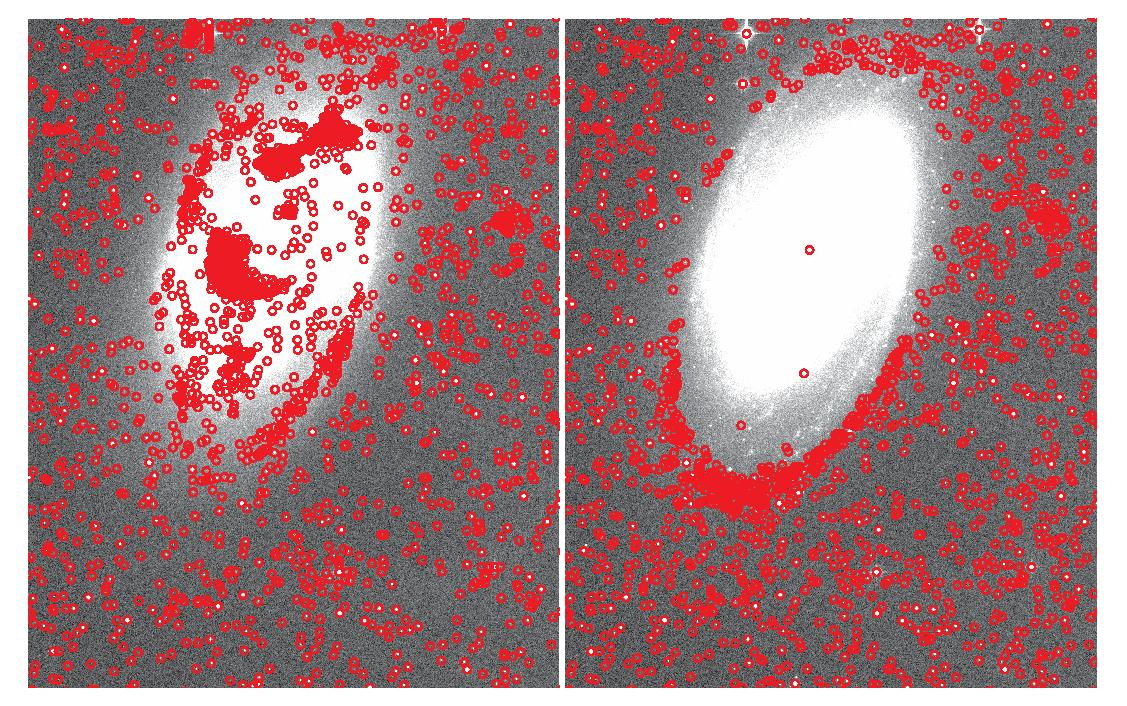

## Astrometry comparison

In order to compare the astrometry performences of mextractor with other tools we run it on two PTF images of the same field, matched the stars, register the images (always using the same procedure), and calculated the difference in X/Y position between the two images.

The results indicate that the astrometric precision of mextractor and SExtractor are identical to within the uncertanties.


% retrieve some PTF images using VO.PTF.wget_corrim
%VO.PTF.wget_corrim([100037 2],[],'JD',[celestial.time.julday([20 11 2012]), celestial.time.julday([23 11 2012])],'Filter','R','save','icp');
VO.PTF.wget_corrim([100037 2],[],'JD',[celestial.time.julday([20 11 2014]), celestial.time.julday([23 11 2014])],'Filter','R','save','icp');


PTF_201411205388_i_p_scie_t125555_u023050416_f02_p100037_c02.fits  


PTF_201411204943_i_p_scie_t115144_u023050379_f02_p100037_c02.fits  


PTF_201411225028_i_p_scie_t120406_u022881502_f02_p100037_c02.fits  


PTF_201411225468_i_p_scie_t130720_u022881475_f02_p100037_c02.fits  


PTF_201411205388_i_p_scie_t125555_u023050416_f02_p100037_c02.fits  


PTF_201411204943_i_p_scie_t115144_u023050379_f02_p100037_c02.fits  


PTF_201411225028_i_p_scie_t120406_u022881502_f02_p100037_c02.fits  


PTF_201411225468_i_p_scie_t130720_u022881475_f02_p100037_c02.fits  


PTF_201411205388_c_p_scie_t125555_u023050416_f02_p100037_c02.ctlg  


PTF_201411204943_c_p_scie_t115144_u023050379_f02_p100037_c02.ctlg  


PTF_201411225028_c_p_scie_t120406_u022881502_f02_p100037_c02.ctlg  


PTF_201411225468_c_p_scie_t130720_u022881475_f02_p100037_c02.ctlg  


PTF_201411205388_c_p_scie_t125555_u023050416_f02_p100037_c02.ctlg  


PTF_201411204943_c_p_scie_t115144_u023050379_f02_p100037_c02.ctlg  


PTF_201411225028_c_

% Read images to SIM arrays
%S1=FITS.read2sim('PTF_201211213383_i_p_scie_t080710_u014664919_f02_p100037_c02.fits');
%S2=FITS.read2sim('PTF_201211223616_i_p_scie_t084044_u014676172_f02_p100037_c02.fits');
S1=FITS.read2sim('PTF_201411204943_i_p_scie_t115144_u023050379_f02_p100037_c02.fits');
S2=FITS.read2sim('PTF_201411205388_i_p_scie_t125555_u023050416_f02_p100037_c02.fits');

% find stars
S1=mextractor(S1);

  Set gain to 1
mextractor first pass - Constructing optimal PSF
  Set gain to 1
  No filter found - Use DefFilter
  Estimate images background and std


 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 159696.344677 



  Subtract background
mextractor image 1 out of 1
  Filter image number 1 - use 1 filters
    Threshold image and locate local maxima
    Extracting 2671 sources
  Calculate 1st and 2nd moments


mextractor second pass - Source detection and measurments
  Subtract background


mextractor image 1 out of 1
  Filter image number 1 - use 2 filters
    Threshold image and locate local maxima
    Extracting 5505 sources
  Calculate 1st and 2nd moments
    Calculate PSF photometry
    Calculate IL aperture photometry (using aper_phot)


S2=mextractor(S2);

  Set gain to 1
mextractor first pass - Constructing optimal PSF
  Set gain to 1
  No filter found - Use DefFilter
  Estimate images background and std


 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 148347.162682 



  Subtract background
mextractor image 1 out of 1
  Filter image number 1 - use 1 filters
    Threshold image and locate local maxima
    Extracting 2547 sources
  Calculate 1st and 2nd moments


mextractor second pass - Source detection and measurments
  Subtract background


mextractor image 1 out of 1
  Filter image number 1 - use 2 filters
    Threshold image and locate local maxima
    Extracting 5353 sources
  Calculate 1st and 2nd moments
    Calculate PSF photometry
    Calculate IL aperture photometry (using aper_phot)


% align images
TranC =  TranClass({@FunOne, [],@FunX,[],@FunY,[],@FunTiltXp,[],@FunTiltXn,[]}, {@FunOne, [],@FunX,[],@FunY,[],@FunTiltYp,[],@FunTiltYn,[] });
%ParDeg = [1 1;2 0;0 2;2 1;1 2];
%TranC =  TranClass({@FunOne, [],@FunX,[],@FunY,[],@FunPolyChebyshev1XY,ParDeg}, {@FunOne, [],@FunX,[],@FunY,[],@FunPolyChebyshev1XY,ParDeg});

[S1a,FR] = align(S1,S2,'TranC',TranC); % note WCS of S1a is incorrect

Iep =      1


Iep =      2


SIM/transform: WCS was not corrected


% find stars in the aligned image
S1a=mextractor(S1a); 

  Set gain to 1
  Subtract background


mextractor image 1 out of 1
  Filter image number 1 - use 2 filters
    Threshold image and locate local maxima
    Extracting 5442 sources
  Calculate 1st and 2nd moments
    Calculate PSF photometry
    Calculate IL aperture photometry (using aper_phot)


% match aligned catalogs
S1m = match(S1a,S2,'SkipWCS',true);
% difference in [X,Y] coordinates between the two images
DXY = S1m.Cat(:,1:2) - S2.Cat(:,1:2);
Mag = S2.Cat(:,20); % PSF mag

% do the same using SExtractor
% SExtractor can't work with NaNs
S1a = replace(S1a,[NaN NaN],nanmedian(S1a));
S1s=ImUtil.Im.sextractor(S1a);

[1M> 
[1A----- SExtractor 2.5.0 started on 2017-09-05 at 14:16:20 with 1 thread

[1M> Setting catalog parameters
[1A[1M> Reading detection filter
[1A[1M> Initializing catalog
[1A[1M> Looking for tp937023c5_fa33_4f71_bb4f_828fadfd42d3.fits
[1AMeasuring from: "TILU_Spring_2014"  / 2048 x 4096 / 32 bits FLOATING POINT data
Detection+Measurement image: [1M> Setting up background maps
[1A[1M> Setting up background map at line:  128
[1A[1M> Setting up background map at line:  256
[1A[1M> Setting up background map at line:  384
[1A[1M> Setting up background map at line:  512
[1A[1M> Setting up background map at line:  640
[1A[1M> Setting up background map at line:  768
[1A[1M> Setting up background map at line:  896
[1A[1M> Setting up background map at line: 1024
[1A[1M> Setting up background map at line: 1152
[1A[1M> Setting up background map at line: 1280
[1A[1M> Setting up background map at line: 1408
[1A[1M> Setting up background map at line: 1536
[1A[1M> Setting up background map at line

S2s=ImUtil.Im.sextractor(S2);

[1M> 
[1A----- SExtractor 2.5.0 started on 2017-09-05 at 14:16:25 with 1 thread

[1M> Setting catalog parameters
[1A[1M> Reading detection filter
[1A[1M> Initializing catalog
[1A[1M> Looking for tpf4add99c_99fa_4396_8c67_8db3967d1ca4.fits
[1AMeasuring from: "TILU_Spring_2014"  / 2048 x 4096 / 32 bits FLOATING POINT data
Detection+Measurement image: [1M> Setting up background maps
[1A[1M> Setting up background map at line:  128
[1A[1M> Setting up background map at line:  256
[1A[1M> Setting up background map at line:  384
[1A[1M> Setting up background map at line:  512
[1A[1M> Setting up background map at line:  640
[1A[1M> Setting up background map at line:  768
[1A[1M> Setting up background map at line:  896
[1A[1M> Setting up background map at line: 1024
[1A[1M> Setting up background map at line: 1152
[1A[1M> Setting up background map at line: 1280
[1A[1M> Setting up background map at line: 1408
[1A[1M> Setting up background map at line: 1536
[1A[1M> Setting up background map at line

S1sm=match(S1s,S2s,'SkipWCS',true);
DXYs=S1sm.Cat(:,1:2) - S2s.Cat(:,1:2);
Mags = S2s.Cat(:,5);  % aper mag.

Nm = size(S2.Cat,1);
Ns = size(S2s.Cat,1);
CC = zeros(0,5);
K = 0;
for Im=1:1:Nm
    
    D = Util.Geom.plane_dist(S2.Cat(Im,1),S2.Cat(Im,2),S2s.Cat(:,1),S2s.Cat(:,2));

            Id = find(D<2);

    if (numel(Id)==1)
        K = K + 1;
        CC(K,:) = [DXY(Im,:), DXYs(Id,:), Mag(Im)];

ans =       0.14207


    end

ans =      0.005009


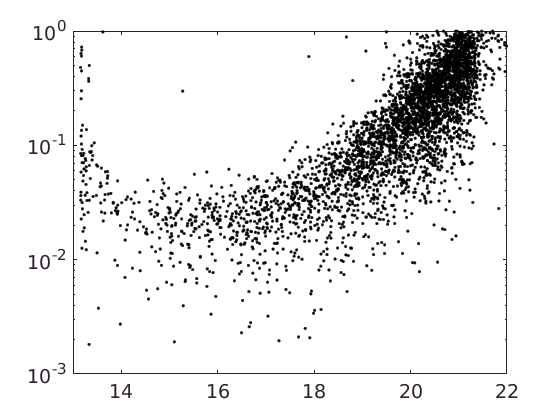

end
Dm=sqrt(sum(CC(:,1:2).^2,2));
Ds=sqrt(sum(CC(:,3:4).^2,2));

nanmedian(Dm-Ds)                % mextractor is a bit better: (19+/-5) mpix
nanstd(Dm-Ds)./sqrt(numel(Ds))  

semilogy(CC(:,5)+6.5,Dm,'k.')
axis([13 22 1e-3 1e0]);
%print MextractorAstrom.eps -depsc2


D1 = FITS.read_table('PTF_201411204943_c_d_scie_t115144_u023050379_f02_p100037_c02.ctlg');
D2 = FITS.read_table('PTF_201411205388_c_d_scie_t125555_u023050416_f02_p100037_c02.ctlg');

D1.ColCell{2} = 'XWIN_IMAGE';
D1.ColCell{3} = 'YWIN_IMAGE';
D1.ColCell{4} = 'ALPHAWIN_J2000';
D1.ColCell{5} = 'DELTAWIN_J2000';
D2.ColCell{2} = 'XWIN_IMAGE';
D2.ColCell{3} = 'YWIN_IMAGE';
D2.ColCell{4} = 'ALPHAWIN_J2000';
D2.ColCell{5} = 'DELTAWIN_J2000';
D1 = colcell2col(D1);
D2 = colcell2col(D2);

D1m = match(D1,D2);


## Photometry comparison